## Field report 

% Import things
config.gen.savepath = '/home/jacob/Projects/ent_loc/dat/'; % office machine
config.gen.num_samples = 8;
config.gen.num_vecs = 10;
config.gen.L = 12;
config.gen.verbose = true;
config.gen.profile = true;
config.gen.Ws = linspace(1,7,10);
clear net_data;
net_data = cell(numel(config.gen.Ws,1));
for N=1:numel(config.gen.Ws)
    fname = [config.gen.savepath,'L-',num2str(config.gen.L),'-W',num2str(config.gen.Ws(N)),...
        '-N',num2str(config.gen.num_vecs),'-PBC.mat'];
    data = load(fname);
    net_data{N} = get_network_data(data);
    clear data
end

# Gross spectral properties of Aleph matrix

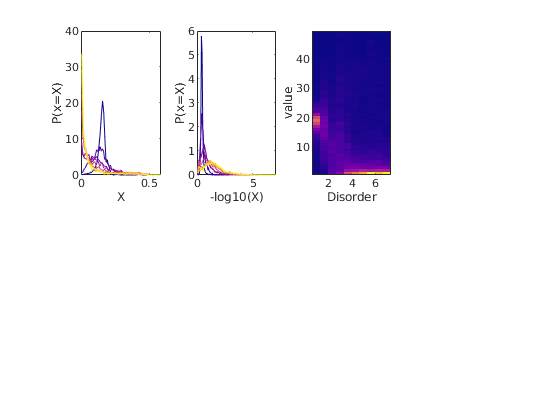

aleph_spec = cellfun(@(x) x.A.eigs/12, net_data,'UniformOutput',false);
config.viz.num_bins = 50;
config.viz.scaling = true;
spec_viz=distribution_viz(aleph_spec,'A spectrum',config);

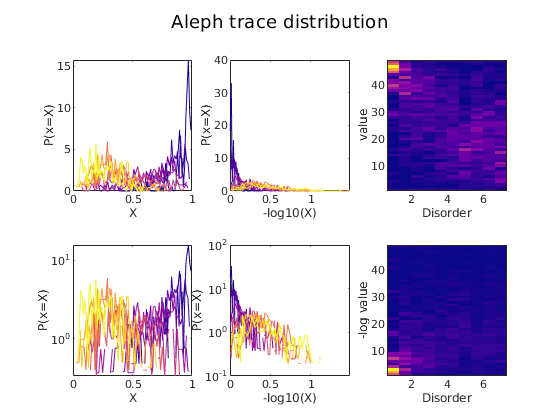

aleph_trc = cellfun(@(x) x.A.trcs, net_data,'UniformOutput',false);
config.viz.scaling = true;
distribution_viz(aleph_trc,'Aleph trace distribution',config);

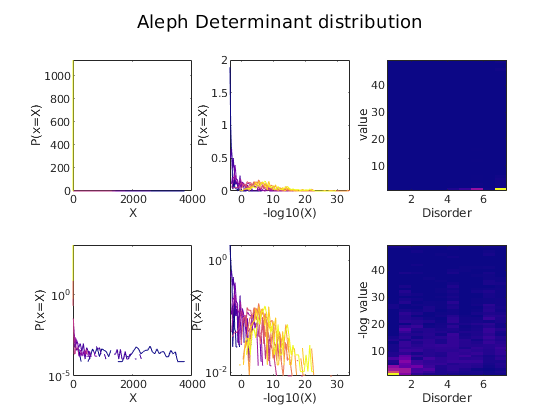

aleph_det = cellfun(@(x) x.A.dets, net_data,'UniformOutput',false);
config.viz.scaling = false;
distribution_viz(aleph_det,'Aleph Determinant distribution',config);

# Detailed spectral properties

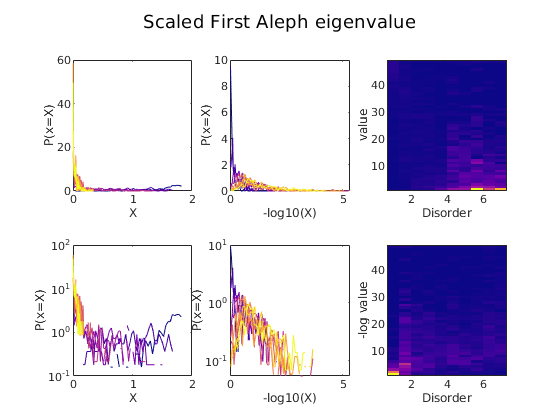

aleph_fielder = cellfun(@(x) x.A.eigs(:,:,end-1), net_data,'UniformOutput',false);
config.viz.scaling = true;
distribution_viz(aleph_fielder,'Scaled First Aleph eigenvalue' ,config);

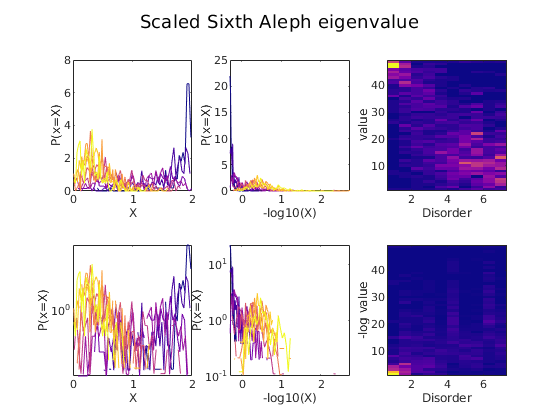

aleph_fielder = cellfun(@(x) x.A.eigs(:,:,end-6), net_data,'UniformOutput',false);
config.viz.scaling = false;
distribution_viz(aleph_fielder,'Scaled Sixth Aleph eigenvalue' ,config) ;

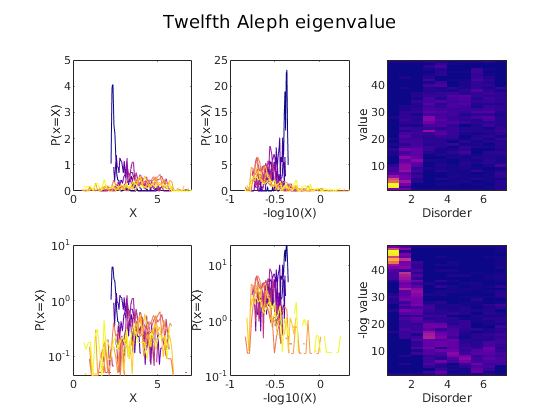

aleph_fielder = cellfun(@(x) x.A.eigs(:,:,1), net_data,'UniformOutput',false);
config.viz.scaling = false;
distribution_viz(aleph_fielder,'Twelfth Aleph eigenvalue',config);

# Structural properties of the Aleph graph object

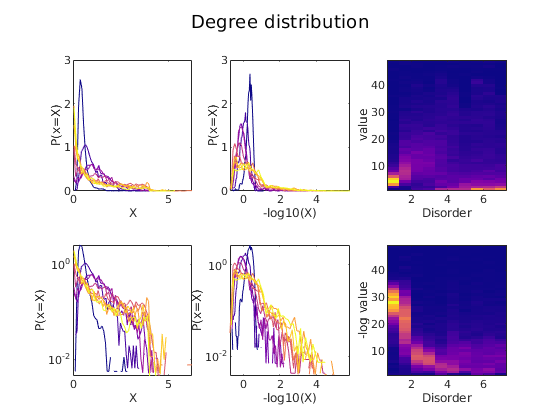

degree_dist = cellfun(@(x) x.degree_list, net_data,'UniformOutput',false);
distribution_viz(degree_dist,'Degree distribution',config);

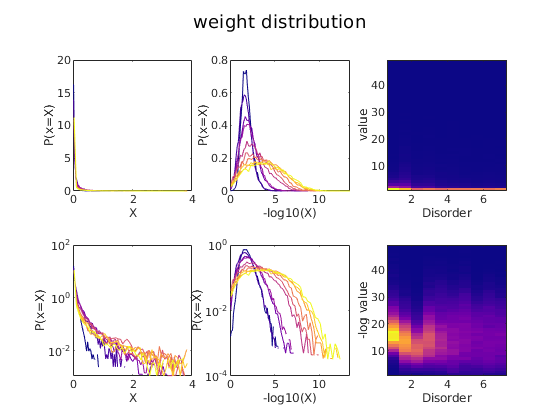

weight_dist = cellfun(@(x) x.weight_list, net_data,'UniformOutput',false);
distribution_viz(weight_dist,'weight distribution',config);

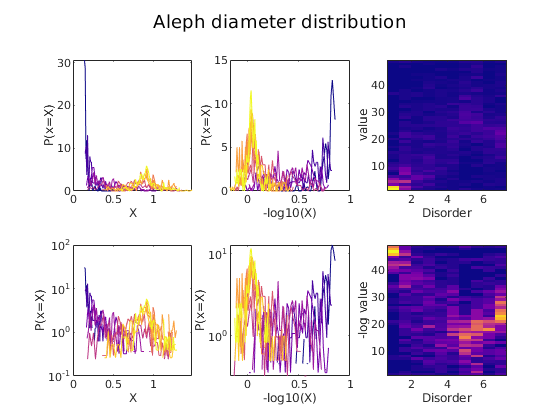

aleph_diam = cellfun(@(x) x.A.diam, net_data,'UniformOutput',false);
config.viz.scaling = false;
distribution_viz(aleph_diam,'Aleph diameter distribution',config);

# Information content

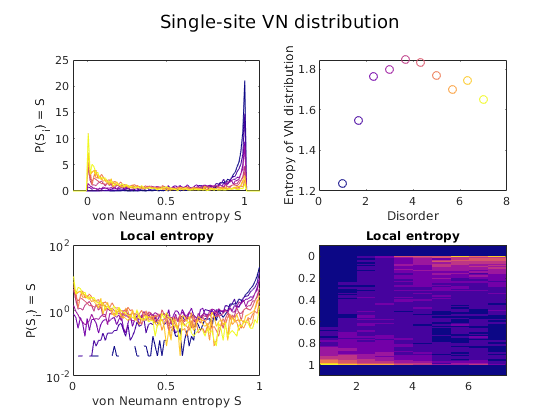

% VN gets special treatment
entropy_viz(net_data,config.gen.Ws);

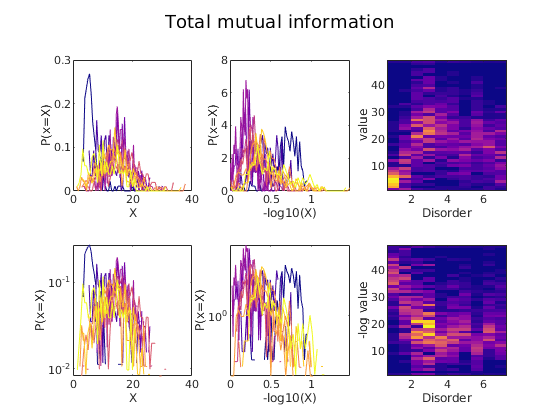

total_immersion = cellfun(@(x) x.A.nonlocality, net_data,'UniformOutput',false);
config.viz.scaling = true;
distribution_viz(total_immersion,'Total mutual information',config);

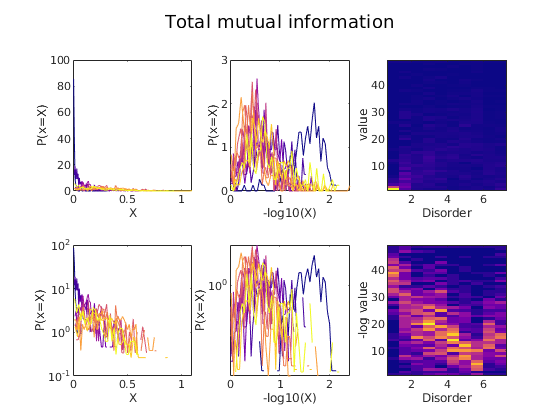

total_immersion = cellfun(@(x) x.A.eta, net_data,'UniformOutput',false);
distribution_viz(total_immersion,'Total mutual information',config);

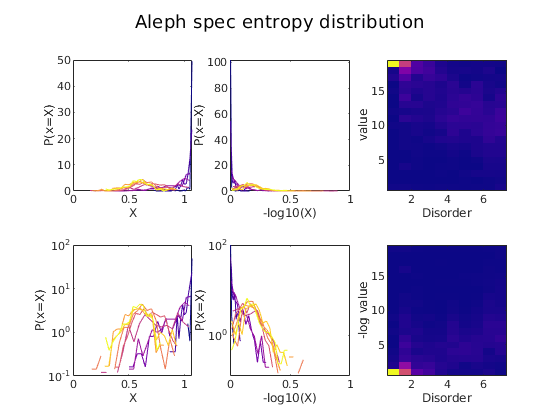

config.viz.scaling = true;
config.viz.num_bins = 20;
aleph_ent = cellfun(@(x) x.A.ents, net_data,'UniformOutput',false);
distribution_viz(aleph_ent,'Aleph spec entropy distribution',config);